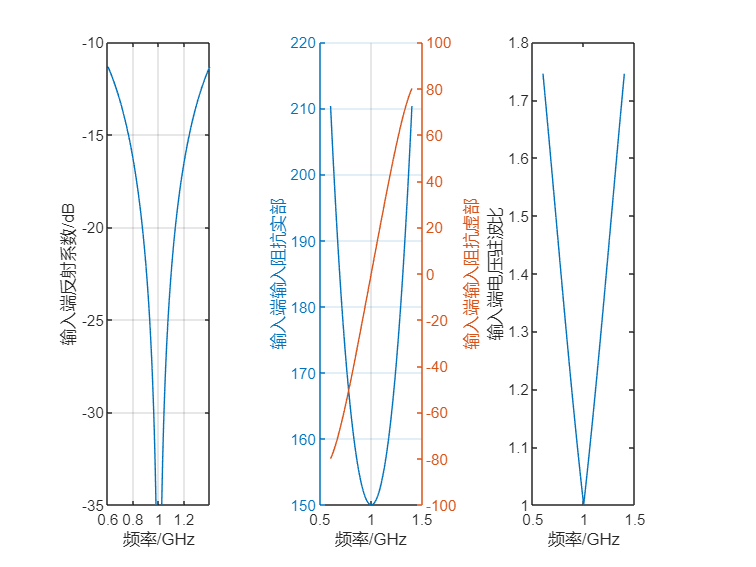

%%%%%%%%%%实验条件%%%%%%%%%%
Z0=150;
ZL=250+100i;
%%%%%%%%%%公式代入%%%%%%%%%%
%1.终端反射系数
gamma_0=(ZL-Z0)/(ZL+Z0);
%2.终端驻波比
ruo0=abs((1+abs(gamma_0))/(1-abs(gamma_0)));
%3.Z01=sart(Z0*R1),代入 R1=Z0*ruo0
Z01=Z0*sqrt(ruo0);
%4.反射系数相角
phase_0=angle(gamma_0);
%5.电长度 l1
electrical_length_01=phase_0/2;
%6.电长度 l2
electrical_length_02=pi/2;
%7.频率范围
relative_f=0.6:0.00001:1.4;
%8.电长度换算的角度值
theta1=electrical_length_01*relative_f;
theta2=electrical_length_02*relative_f;
%9.计算输入阻抗
Zin2=zeros(1,length(relative_f));
%9.计算变量分布
for k=1:length(relative_f)
Zin2(k)=F1(Z01, theta2(k), F1(Z0, theta1(k), ZL));
end
gamma=(Zin2-Z0)./(Zin2+Z0);
%%%%%%%%%%绘制图像%%%%%%%%%%
%输入端反射系数
figure(1);
subplot(1,3,1);
plot(relative_f,20*log10(abs(gamma)));
xlabel('频率/GHz');
ylabel('输入端反射系数/dB');
axis([0.6,1.4,-35,-10]);
grid on;
%输入端输入阻抗实部虚部
subplot(1,3,2);
hold on;
yyaxis left
plot(relative_f,real(Zin2));
xlabel('频率/GHz');
ylabel('输入端输入阻抗实部');
yyaxis right;
plot(relative_f,imag(Zin2));
xlabel('频率/GHz');
ylabel('输入端输入阻抗虚部');
grid on;
%输入端电压驻波比
subplot(1,3,3);
abs_rou=abs((1+abs(gamma))./(1-abs(gamma)));
plot(relative_f,abs_rou);
xlabel('频率/GHz');
ylabel('输入端电压驻波比');

function Zin =F1(Z0, theta, ZL)
Zin=Z0.*(ZL*cos(theta)+Z0*sin(theta)*1i)./(Z0*cos(theta)+ZL*sin(theta)*1i);
end